## Introduction

This interactive notebook steps through examples in Lauren Fink's Pupil Time Series workshop, which was part of a larger Pupillometry Workshop, held April 4-5th, 2022, at the University of Oslo, Centre for Interdisciplinary Studies in Rhythm, Time, and Motion (RITMO). More information about the workshop can be found here: [https://www.uio.no/ritmo/english/projects/ritpart/events/workshops/2022/pupillometry/index.html](https://www.uio.no/ritmo/english/projects/ritpart/events/workshops/2022/pupillometry/index.html) 

Much of the content in this tutorial comes from my recent review paper, which is currently under peer review: 

- Fink, L., Simola, J., Tavano, A., Lange, E. B., Wallot, S., & Laeng, B. (2021, December 2). From pre-processing to advanced dynamic modeling of pupil data. [https://doi.org/10.31234/osf.io/wqvue](https://doi.org/10.31234/osf.io/wqvue)

as well as my previous paper applying these concepts in the realm of pupillometry + percussive music:

- Fink, L. K., Hurley, B. K., Geng, J. J., & Janata, P. (2018). A linear oscillator model predicts dynamic temporal attention and pupillary entrainment to rhythmic patterns. *Journal of Eye Movement Research*, *11*(2). [https://doi.org/10.16910/jemr.11.2.12](https://doi.org/10.16910/jemr.11.2.12) 

The goal of this interactive notebook is to provide users with a more in-depth understanding of a few critical concepts. We will focus on convolution and time-frequency analyses. 

#### About this code:

All of the code (including this script) and data for this workshop can be found in the following repository: [https://github.com/lkfink/RITMO_pupil_workshop](https://github.com/lkfink/RITMO_pupil_workshop) 

If using anything from this script in future publications, please cite one or both of the above papers. 

Contact: lauren.fink@ae.mpg.de 

## Tutorial

### Load toy data set

As long as you have not moved any files around in the folder you downloaded that contains this script, you should have no problem loading the appropriate files and functions. 

These toy data come from the much larger data set reported in this paper: 

- Lange, E. B., Zweck, F., & Sinn, P. (2017). Microsaccade-rate indicates absorption by music listening. *Consciousness and cognition*, *55*, 59-78.

Please do not distribute any of these data or use them in future publications. 

Note that in the toy data set provided, I have already pre-processed the pupil data by removing data during blinks and saccades, linearly interpolating missing data, high-pass filtering at .05 Hz, downsampling to 100 Hz, and z-scoring per trial. Pre-processing steps are not the focus of this tutorial, but do warrant their own in depth consideration and discussion. 

% Get name of directory containing this file
working_dir = fileparts(matlab.desktop.editor.getActiveFilename);

% Load data set (loads into structure called pd)
load(fullfile(working_dir, 'Fink_toydata_RITMO.mat'))

## Explore basics of time series

In this section we plot a few time series and explore some fundamental concepts. 

### Plot time series

Let's plot one subject's pupil trace for one stimulus.

% Define parameters for user controls
subs = unique(pd.data.subject);
minsubs = min(subs);
maxsubs = max(subs);

stims = unique(pd.data.stimulus);
minstims = min(stims);
maxstims = max(stims);

Select which subject and stimulus you would like to plot.

Stimulus 6 is Fourtet's *She moves she*

Stimulus 20 is Duke Ellington's *Take the A Train*

selected_sub =16;
selected_stim = 6;
singlesub_pup = cell2mat(pd.data.pupil(pd.data.subject==selected_sub & pd.data.stimulus==selected_stim));

% Plot
figure()
xscale = samps2secs(singlesub_pup, pd.pupil_info.Fs.cleaned);
plot(xscale, singlesub_pup, 'k', 'LineWidth',1)
ylim([-4 4])
xlim([1 30])
ylabel('Pupil size (z-score)')
xlabel('Time (sec)')
set(gcf,'Units', 'inches', 'Position',[5 5 15 5])

N.B.

As you can see, some time series are cleaner than others.

- Look at the data of subject 1 vs. 3. What seems different? The data of subject 1 are less "noisy" than sub 3. What could make subject 3's data look more like subject 1? (answer: a low pass filter that would remove high frequency noise). 

- The toy data provided here were already pre-processed with missing data linearly interpolated. Sometimes so much continigous data may be missing that interpolation looks unnatural. Check out sub 5, stim 20. Look for the visible straight lines going between noisy chunks of data. This type of data will not be a problem for some types of analysis but may be for others. Try to think through what kind of effects it may have (e.g., steep edges create power in higher frequency bands). 

### Time series vs. averages

To gain a sense of why it might be interesting to look at a full time series, let's visualize what is going on when we use means vs time series.

First, let's plot the mean of our time series for the stimulus selected above vs. the mean over the whole stimulus. Error represents the variability across participants. 

Check this box if you would like to see the standard deviation, otherwise the standard error of the mean will be plotted. 

plot_std = false;% Flag whether to plot std (check) or not

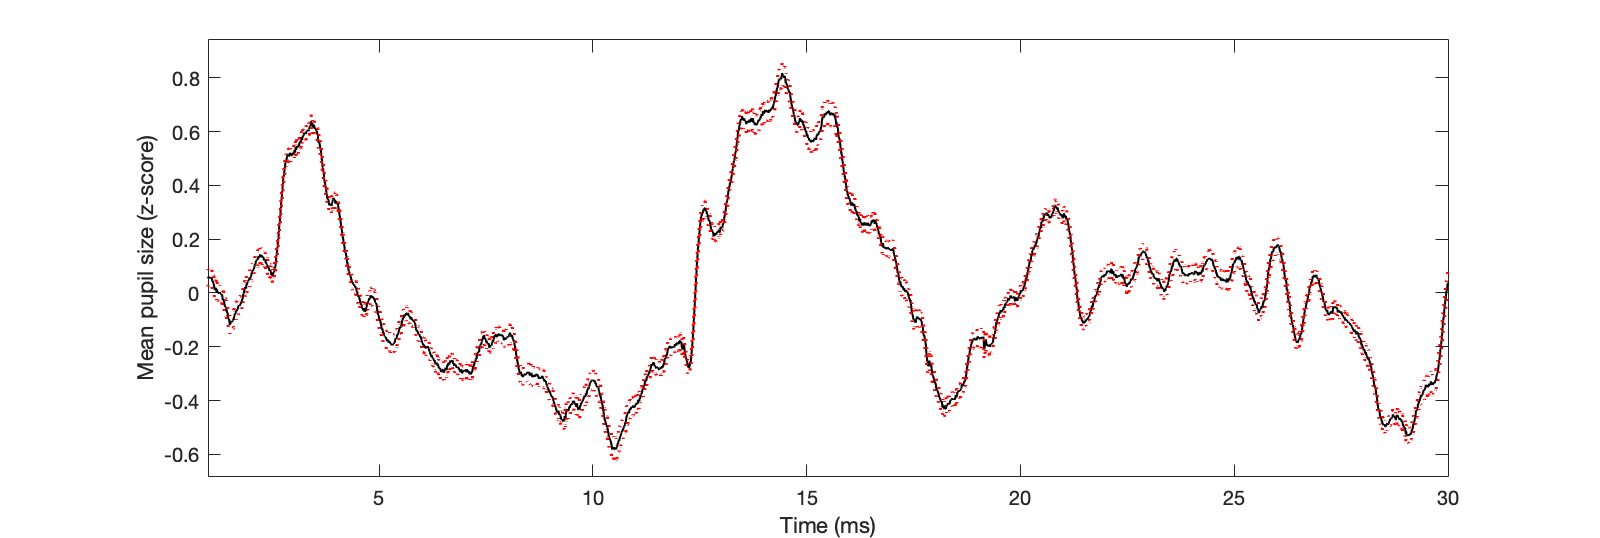

% Get the average pupil time series for selected stimulus
pupdata_selected_stim = cell2mat(pd.data.pupil(pd.data.stimulus==selected_stim));
avgpup = mean(pupdata_selected_stim);
stdpup = std(pupdata_selected_stim);
sempup = stdpup / size(pupdata_selected_stim, 1);

% Plot time series average
figure()
xscale = samps2secs(avgpup, pd.pupil_info.Fs.cleaned);
plot(xscale, avgpup, 'k', 'LineWidth',1)
hold on
if plot_std
    errordata = stdpup;
else
    errordata = sempup;
end
plot(xscale, avgpup+errordata, ':r', 'LineWidth',1) % upper error
hold on
plot(xscale, avgpup-errordata, ':r', 'LineWidth',1) % lower error
ylim([min(avgpup-errordata)*1.1 max(avgpup+errordata)*1.1])
xlim([1 30])
ylabel('Mean pupil size (z-score)')
xlabel('Time (sec)')
set(gcf,'Units', 'inches', 'Position',[5 5 15 5])

% Get the average pupil size for selected stimulus, for each subject
avgpup_subs = mean(pupdata_selected_stim, 2); % 2 for second dim
stdpup_subs = std(pupdata_selected_stim,0,2); %no weighting, 2nd dim
sempup_subs = stdpup_subs / size(pupdata_selected_stim, 1);

% Choose which error data to proceed with
if plot_std
    errordata = stdpup_subs;
else
    errordata = sempup_subs;
end

% Get mean over all subs
mean_err = mean(errordata);
mean_subs = mean(avgpup_subs);
% Plot averages of time series
figure()
plot(1,mean_subs, 'ko', 'MarkerFaceColor','k', 'MarkerSize',10)
hold on
errorbar(1,mean_subs,mean_subs-mean_err,mean_subs+mean_err);
ylim([min(mean_subs-mean_err)*1.1 max(mean_subs+mean_err)*1.1])
ylabel('Mean pupil size (z-score)')
set(gca,'xtick',[])
set(gcf,'Units', 'inches', 'Position',[5 5 15 5])

As we can see from these two plots, we get vastly different information depending on the approach we take. While on average over time, the pupil size is 0 (bottom plot), it is clear from the top plot that there are certain moments in time when the pupil size average is well above or below zero. For example, if looking at the data for stimulus 6, there seem to be three major peaks in our time series (around 400, 1500, 2200). For stimulus 20, there are not such clear section breaks, but rather a lot of fluctuation throughout. 

*What if we want to relate the pupil time series to the musical stimulus participants were listening to? *

### Music as a time series

If you want to listen to the stimulus selected above, use the following controls: 

% Get the amplitude envelope of one music stimulus
music = pd.stimulus_info.audio_original{pd.stimulus_info.ID == selected_stim}; % Our selected stimulus
player = audioplayer(music, pd.stimulus_info.Fs.original);

 
play(player)

 
pause(player)

 
resume(player)

 
stop(player)

Let's plot the raw audio.

figure()
xscale = samps2secs(music(:,1), pd.stimulus_info.Fs.original);
plot(xscale, music(:,1), 'k')
xlabel('Time (secs)')
ylabel('Amplitude')
set(gcf,'Units', 'inches', 'Position',[5 5 15 5])

#### Filtering 

As we can see from the plot above, our audio signal is really densely sampled. Do we actually think the pupil could keep up with changes at 44.1k? - absolutely not! The pupil's ability to move (constrict / dilate) seems to occur mostly in the 0-4 Hz range. When filtering, you should always set the frequency cut-off to be at least double the highest frequency you are interested in. So in this case, we want to make sure we can observe activity up to 4 Hz, therefore, our frequency cutoff should be at least 8 Hz. We can low-pass filter at 10 Hz just to be safe. 

Also, our pupil data are sampled at 100 Hz. We should downsample our audio data to match our pupil data. Further, we can also see from the waveform that the amplitude is symmetric about zero, so we can proceed with only the upper portion of our amplitude envelope. 

Below, we plot our new audio signal after extracting the upper amplitude envelope, low-pass filtering at 10 Hz, and downsampling to 100 Hz, and z-scoring. 

To get an idea of what a filter does, you can mess around with the frequency of the low pass filter. Note though, that some frequencies might require a different order or type of filter. Right now the order is set to 3rd Butterworth. Designing good filters is not the focus of this tutorial, but I can recommend the following article: 

- de Cheveigné, A., & Nelken, I. (2019). Filters: when, why, and how (not) to use them. *Neuron*, *102*(2), 280-293.

lowpass_cutoff_freq = 3;
N = 100*.05; % 50ms window for envelope function
[YUPPER,YLOWER] = envelope(music, N, 'rms'); % Our envelope. Proceed with just the upper portion (they are symmetrical)
[b,a] = butter(3, lowpass_cutoff_freq/(pd.stimulus_info.Fs.original/2), 'low'); % lowpass filter envelope at 10Hz.
filtaud = filtfilt(b,a,YUPPER(:,1));
music_env = zscore(filtaud);
[p,q] = rat(pd.pupil_info.Fs.cleaned / pd.stimulus_info.Fs.original); % desired fs / original fs
music_env_ds = resample(music_env, p, q);

figure()
xscale = samps2secs(music_env_ds, pd.pupil_info.Fs.cleaned);
plot(xscale, music_env_ds, 'k')
xlabel('Time (secs)')
ylabel('Amplitude')
set(gcf,'Units', 'inches', 'Position',[5 5 15 5])

begin = pd.pupil_info.Fs.cleaned * 5; % 5 secs into music
datalen = pd.pupil_info.Fs.cleaned * 30; % want to take 30 secs of data
music_excerpt = music_env_ds(begin:begin+datalen);

Notice that at lower cutoff frequencies our stimulus time course looks more on the scale of what we might imagine from the pupil. 

Note that the pupil data provided in this toydata set are from seconds 5 - 35 of the stimulus, so we will now trim our audio data to match our pupil data. 

### Relating our two time series

*Now how can we relate the two signals (music and pupil)?*

figure()
% plot stimulus
subplot(3,1,1) 
xscale = samps2secs(music_excerpt, pd.stimulus_info.Fs.downsampled);
plot(xscale, music_excerpt, 'k')
xlim([1 30])
ylabel('Amp. Env. (z-score)')
title('Stimulus')
hold on
% plot pupil 
subplot(3,1,2)
plot(xscale, avgpup, 'm')
ylabel('Avg. pup (z-score)')
title('Pupil')
xlim([1 30])

% plot the two traces overlaid on each other
subplot(3,1,3)
yyaxis left
plot(xscale, music_excerpt, 'k')
ylabel('amp env')
hold on
yyaxis right
plot(xscale, avgpup, 'm', 'LineWidth',2)
ylabel('pup')
xlabel('Time (ms)')
xlim([1 30])
ax = get(gca);
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'm';
title('Overlaid signals')

There are a variety of possible options for how to assess their relation. We will step through a few options. 

## Convolution

Perhaps our goal is to understand the transfer function between the two signals above. We can think of our music as a function m(t) and our pupil as a function p(t). To understand the relation between these two functions, we want to solve for a third function that relates the two. 

Actually, though, we don't need to solve for such a transfer function because it has already been empirically derived by others! For example Hoeks & Levelt (1993) defined the pupil impulse response function (PRF) as follows: 


$$\textrm{PRF}=t^n e^{\left(-\;\frac{\textrm{nt}}{t_{\max } }\right)}$$


*t* = delay until pupil size returns to basline

*n* = number of neural signaling steps between impulse and pupil response

*t_max* = pupil response peak latency 

To determine the parameters of this function, they had participants listen to auditory tones and respond with a button press. 

From known input and measured output, they fit the following function that defines the input-output relationship:

figure()
prf = genPRF(pd.pupil_info.Fs.cleaned, 1);
xscale = samps2secs(prf, pd.pupil_info.Fs.cleaned); % convert to secs
plot(xscale, prf, 'k', 'Linewidth', 2)
xlim([0 3]);
ylimMotor = get(gca, 'Ylim');
xlabel('Time (sec)')
ylabel('Pupil size [a.u.]')
title('PRF, motor response required')
set(gcf,'Units', 'inches', 'Position',[5 5 5 2])

Later, other researchers (e.g., McCloy et al., 2016) showed that the constants defined in this response function differ, depending on whether participants need to make a button press. If no button press is required the pupil takes less time to return to baseline. The amplitude of the response is also less, though that is hard to tell from the scaling of these axes.

prf = genPRF(pd.pupil_info.Fs.cleaned, 0); % 0 for no motor response

% plot
figure()
xscale = samps2secs(prf, pd.pupil_info.Fs.cleaned);
plot(xscale, prf, 'k', 'Linewidth', 2)
xlim([0 3]) % so can compare with previous prf
ylim(ylimMotor/100) % scale axis so comparable and visible
xlabel('Time (sec)')
ylabel('Pupil size [a.u.]')
title('PRF, no motor response')
set(gcf,'Units', 'inches', 'Position',[5 5 5 2])

Still later, others have shown that the parameters of the PRF are highly consistent within an individual but do vary across individuals (Denison et al., 2020). Therefore, future research might consider a task to first calculate each individual's PRF. 

#### Further Reading

- Hoeks, B., & Levelt, W. J. (1993). Pupillary dilation as a measure of attention: A quantitative system analysis. *Behavior Research methods, instruments, & computers*, *25*(1), 16-26.

- McCloy, D. R., Larson, E. D., Lau, B., & Lee, A. K. (2016). Temporal alignment of pupillary response with stimulus events via deconvolution. *The Journal of the Acoustical Society of America*, *139*(3), EL57-EL62.

- Denison, R. N., Parker, J. A., & Carrasco, M. (2020). Modeling pupil responses to rapid sequential events. *Behavior research methods*, *52*(5), 1991-2007.

### Building intuition about how convolution works

Let's mess around a bit with impulse trains and our pupil response function. 

Set the inter-onset-interval of the impulses you want to input (in ms):

impulseIOI = 3000;

Next decide if you want all impulses to be the same amplitude or different. The number you input will accent every x impulse (e.g. by inputting 4, every 4th impulse will be greater in amplitude). 

weight = 0;

Next decide whether you want to use the motor or non-motor PRF. Check the box for motor

motor = true;

% generate series of impulses
impulseTrain = zeros(1,10000);              % initiate empty time series, 10 secs long
impulseTrain(1:impulseIOI:end) = 1;         % insert event every IOI
impulseTrain(1:impulseIOI*weight:end) = 2;  % insert event every IOI

% convolve impulses with PRF

% Generate PRF and predicted pupil trace
prf = genPRF(1000, motor); % 1000 for Fs so keep things in msecs, 1 for motor response
predpup = conv(impulseTrain, prf, 'full');
pred = zscore(predpup); % normalize

% Plot
figure()
subplot(2,1,1)
plot(impulseTrain, 'k')
xlim([-100 numel(pred)+100])
title('Impulse Train')
hold on

subplot(2,1,2)
plot(pred, 'k', 'Linewidth', 1)
xlim([-100 numel(pred)+100])
title('Predicted pupil response')
xlabel('Time (ms)')
set(gcf,'Units', 'inches', 'Position',[1 1 15 5])

### Predicting pupil data

Let's return to our question earlier about relating our stimulus to our recorded pupil data. 

One question we might have is whether the recorded pupil data reflects what would be predicted by convolving our stimulus with the pupillary response function. While participants were listening to this music they did not make any responses, so we will use the non-motor PRF. 

Below we plot the predicted pupil data vs. the recorded pupil data (averaged across participants). 

% Generate PRF and predicted pupil trace
prf = genPRF(pd.pupil_info.Fs.cleaned, 0);
predpup = conv(music_env_ds, prf, 'full'); % do convolution on full music
predpup = predpup(begin:begin+datalen); % now cut to our 30 secs
pred = zscore(predpup); % normalize

% Plot
figure()
xscale = samps2secs(pred, pd.pupil_info.Fs.cleaned);
% plot prediction in black
yyaxis left
plot(xscale, pred', 'k')
ylabel('Predicted')
hold on
% plot pupil in magenta
yyaxis right
plot(xscale, avgpup, 'm', 'LineWidth',2)
xlim([1 30])
xlabel('Time (sec)')
ylabel('Recorded')
set(gcf,'Units', 'inches', 'Position',[5 5 15 5])
ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'm';

There would be a number of ways to relate the above two signals statistically. The method chosen will depend on a variety of factors, and any conclusions made will require appropriate controls on the experimental design side. 

### Convolution summary

Hopefully the examples in this section have provided a starting point for understanding what convolution does and the possible uses for it in your research. Next we move on to time frequency analyses. 

## Time-frequency analyses

A variety of analyses fall under the heading of time-frequency analyses. I highly recommend checking out Mike X. Cohen's book, *Analyzing Neural Time Series. *It is an excellent resource for understanding core concepts and how to code them in MATLAB. Though Cohen's focus is EEG data, consider the pupil a single channel of EEG and most of the same techniques and concepts are applicable. 

Let's step through a few analysis approaches relevant for pupil data.

### Power spectral density

One basic thing we might want to check is whether our two signals show similar spectral profiles (i.e., energy at the same frequencies). Let's plot the spectrum of our pupil.

As stated previously, the pupil cannot change size very quickly. Our main activity of interested will be under 5 Hz. But you can use the slider to plot your frequency range of interest. 

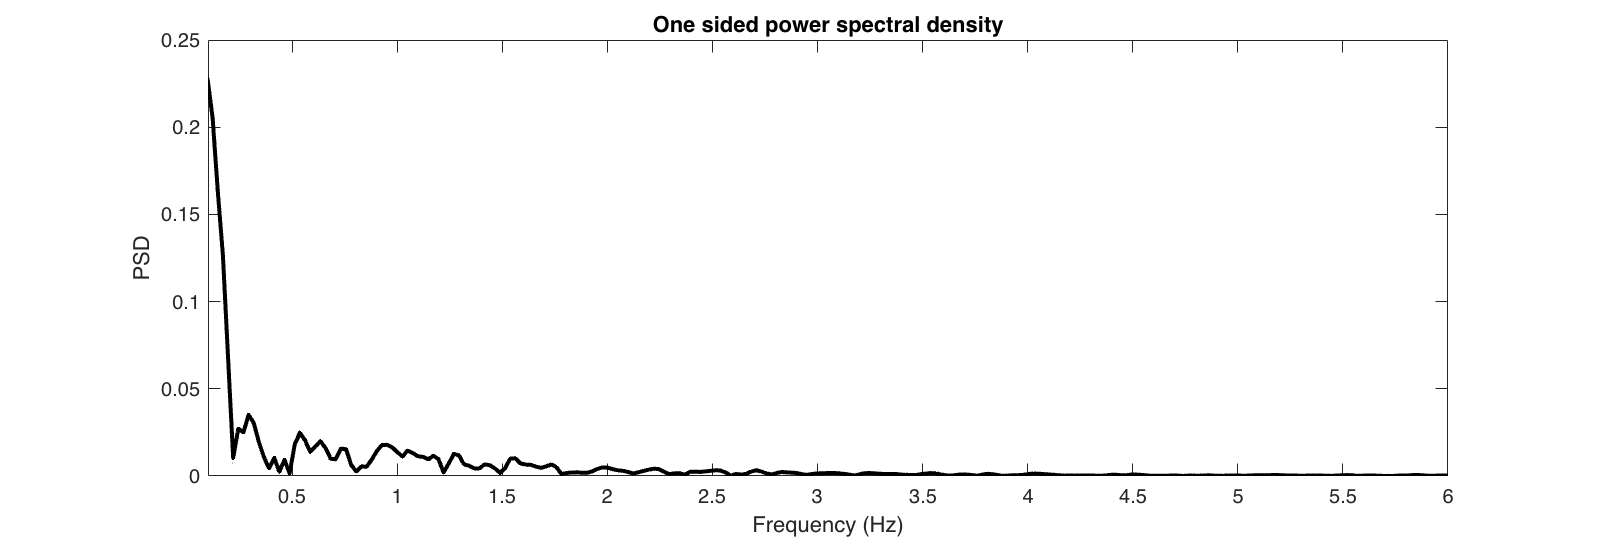

highestFreq = 6;

% Use custom function, included in this repo, to calculate FFT
[FFTresult, power, fVals] = getFFT(avgpup, pd.pupil_info.Fs.cleaned);
%[FFTresult_mus, power_mus, fVals_mus] = getFFT(music_excerpt, pd.pupil_info.Fs.cleaned);

figure()
%yyaxis left
plot(fVals, power, 'k', 'LineWidth',2);
hold on 
%yyaxis right
%plot(fVals_mus, power_mus, 'c', 'LineWidth',2);
hold on
title('One sided power spectral density');
xlabel('Frequency (Hz)')
ylabel('PSD');
xlim([0.1 highestFreq]);
set(gcf,'Units', 'inches', 'Position',[5 5 15 5])

Note that the pupil tends to follow a 1/f power law scaling function (i.e., high power at lower frequencies that decays exponentially). Nonetheless, in certain circumstances, the pupil may exhibit peaks beyond the 1/f background noise. Peaks in the plot represent increased power (y axis) at the corresponding frequency (x axis). One would need to conduct appropriate tests to be sure that a peak is significantly different from noise. Nonetheless, spectral density does not necessarily mean "entrainment." To understand whether the pupil is entrained to some frequency present in a stimulus, it would be necessary to do a phase-based analysis (the topic of the next section).

### Magnitude squared coherence

Magnitude squared coherence is essentially the correlation of the PSD (see above) of the two signals. More precisely, it is the discrete Fourier Transform (DFT) of the cross correlation function of the two signals. Because a DFT involves the assumption of stationarity, one should be careful in considering whether one’s data meet those assumptions and, if not, to use windows of an appropriate length during which stationarity can reasonably be assumed. Both the length of the window over which the DFT is calculated, as well as the overlap chosen between windows, influence the frequency resolution of the resultant power spectral density estimates.

We can compute ms coherence over the entire course of the trial (first plot), or over time by calculating it within multiple windows of a shorter duration. 

Here, you can choose the window length in secs: 

% constants
x = music_excerpt; % put music into x variable
y = avgpup'; % make pupil y and make column vector 
nwin = 256; % window size for fft 
noverlap = round(nwin*.8); % ~80 overlap. Need to round to full integer 
fs = pd.pupil_info.Fs.cleaned;
nfft = nwin*2;

%-------------------------------------------------------------------------%
% Calculate stft
%-------------------------------------------------------------------------%
% first for music
[x1, f1] = stft(x,fs,'Window',kaiser(nwin,5),'OverlapLength',noverlap,'FFTLength',nfft);
x1 = x1(nwin:end,:); % take pos side of result. NOTE still contains imaginary components 
f1 = f1(nwin:end); % take matching frequencies
% now for pupil
y1 = stft(y,fs,'Window',kaiser(nwin,5),'OverlapLength',noverlap,'FFTLength',nfft);
y1 = y1(nwin:end,:);

% set freqs of interest for subsequent analyses
highestFreq = 5;
endind = find(f1 >= highestFreq, 1); % get index of highest freq we are interested in
freqs = 1:endind; % indices of f1

%-------------------------------------------------------------------------%
% Magnitude-Squared Coherence
%-------------------------------------------------------------------------%
clear Cxy
clear Cxytime
Cxy = zeros(1,numel(freqs)); % initialize coherence vector
for iFreq = freqs % loop through frequencies
    for iTime = 1:size(x1,2) % loop through time points for both signals. A bit of a misnomer because actually looping through freq bins
        % power of x multiplied power of y, then multiplied by their
        % difference in phase
        temp(iTime) = abs(x1(iFreq,iTime)).*abs(y1(iFreq,iTime)) .* exp(1i*(angle(x1(iFreq,iTime))-angle(y1(iFreq,iTime)))); % abs val of power of x and y multipled by their phase angle differences
        x1time(iTime) = x1(iFreq,iTime); % save for each time point
        y1time(iTime) = y1(iFreq,iTime);
    end
    % calculate ms coherence between the two signals over time
    Cxy(iFreq) = (abs(mean(temp)).^2)/((mean(abs(x1time).^2))*(mean(abs(y1time).^2)));
end

% MS Coherence over time
windowWidth_secs = 2.5; % set time window width in secs
windowWidth = windowWidth_secs * (1000/pd.pupil_info.Fs.cleaned); % convert to samples
Cxytime = zeros(numel(freqs), size(x1,2)-windowWidth); % initialize output variable
for iFreq = freqs 
    for iTime = 1:size(x1,2)
        temp(iTime) = abs(x1(iFreq,iTime)).*abs(y1(iFreq,iTime)).*exp(1i*(angle(x1(iFreq,iTime))-angle(y1(iFreq,iTime))));
        x1time(iTime) = x1(iFreq,iTime);
        y1time(iTime) = y1(iFreq,iTime);
    end
    
    averagedData = zeros(1, length(temp) - windowWidth);
    for k = 1 : length(temp) - windowWidth % do the same thing as above but for each time point
        averagedData = (abs(mean(temp(k:k+windowWidth-1))).^2)/((mean(abs(x1time(k:k+windowWidth-1).^2)))*(mean(abs(y1time(k:k+windowWidth-1).^2))));
        Cxytime(iFreq,k) = averagedData;
    end
end

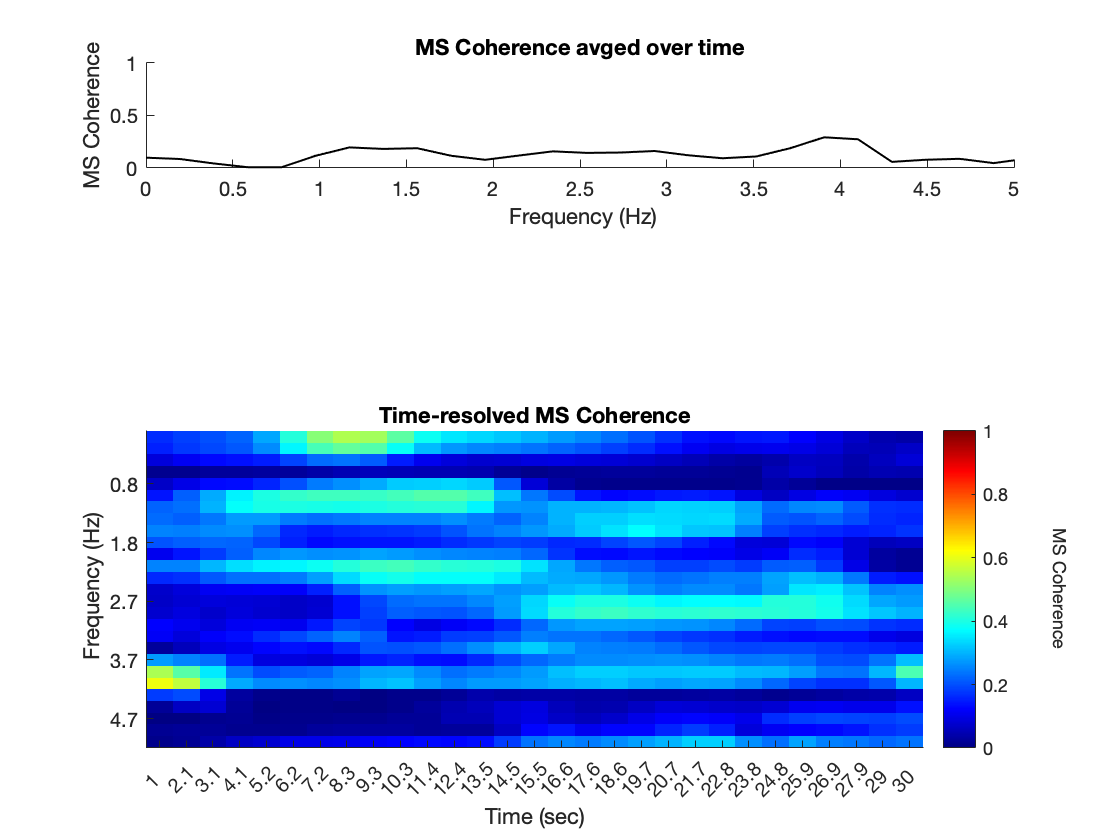

%-------------------------------------------------------------------------%
% Plot results
%-------------------------------------------------------------------------%
figure()
subplot(4,1,1)
plot(f1(freqs), Cxy, 'k', 'LineWidth', 1)
ylabel('MS Coherence')
ylim([0 1])
xlim([0 highestFreq])
xlabel(' Frequency (Hz)')
set(gca,'box','off')
title('MS Coherence avged over time')

% coherence over time
subplot(4,1,3:4)
colormap(jet)
imagesc(Cxytime)
ylabel('Coherence')
yt = get(gca,'ytick');
set(gca,'YTick',yt, 'yticklabel',round(f1(freqs(yt)),1)) 
ylabel(' Frequency (Hz)')
caxis([0 1])

% convert xticks to secs
xts = 1:size(Cxytime,2);
total_dur = size(avgpup, 2) / pd.pupil_info.Fs.cleaned;
ticktimes = round( xts * (total_dur/size(Cxytime,2)) , 1);
set(gca, 'XTick',xts, 'XTickLabel', ticktimes) 

xlabel('Time (sec)')
a = colorbar('EastOutside');
ylabel(a,'MS Coherence', 'Rotation',270);
a.Label.Position(1) = 4;
set(gca,'box','off')
title({'';'Time-resolved MS Coherence'})

For stimulus 20, in the above two plots, we can see a clear peak in phase coherence at ~2.7 Hz, which turns out to be the perceived beat frequency in this music. For stimulus 6, on the other hand, there does not appear to be much phase consistency between the music and the pupil. Do you have any ideas why? Remember, you can listen to both stimuli, and change which one is plotted, by using the controls towards the top of the script. 

## Final discussion

- How do you see such analysis techniques fitting in with your research questions?

- What additional tools do you need to be able to answer your questions of interest?

- What remains unclear from today?

## Additional resources

Choosing appropriate analysis techniques, window sizes, etc. will depend, not only on your understanding of the technique, but also on the length of your recorded data, the type of task participants were doing, the design of your experiment, and so on. Please consult the resources above for more information about analysis techniques. For more information about best practices in pupillometry, in general, please consult the following:

Steinhauer, S. R., Bradley, M. M., Siegle, G. J., Roecklein, K. A., & Dix, A. (2022). Publication guidelines and recommendations for pupillary measurement in psychophysiological studies. *Psychophysiology*, *59*(4), e14035.

Laeng, B., & Alnaes, D. (2019). Pupillometry. In *Eye movement research* (pp. 449-502). Springer, Cham.

Mathôt, S. (2018). Pupillometry: Psychology, physiology, and function. *Journal of Cognition*, *1*(1).